## Configuration Analysis for a Novel Control Law for 3 Link Manipulator

% define all the system variables
syms delta_1 delta_2 delta_3 phi_1 phi_2 phi_3 alpha R l D_11 D_12 D_13 D_21 D_22 D_23 D_31 D_32 D_33

% Compute deltas through geometric analysis
delta_1 = alpha - atan2((sin(phi_1)+sin(phi_1+phi_2)+sin(phi_1+phi_2+phi_3)),(cos(phi_1)+cos(phi_1+phi_2)+cos(phi_1+phi_2+phi_3)))

$$delta\_1 = \alpha -\text{atan2}\left(\sin\left(\varphi_{1}+\varphi_{2}+\varphi_{3}\right)+\sin\left(\varphi_{1}+\varphi_{2}\right)+\sin\left(\varphi_{1}\right),\cos\left(\varphi_{1}+\varphi_{2}+\varphi_{3}\right)+\cos\left(\varphi_{1}+\varphi_{2}\right)+\cos\left(\varphi_{1}\right)\right)$$

delta_2 = atan2((R*sin(alpha)-l*sin(phi_1)),(R*cos(alpha)-l*cos(phi_1))) - atan2((sin(phi_1+phi_2)+sin(phi_1+phi_2+phi_3)),(cos(phi_1+phi_2)+cos(phi_1+phi_2+phi_3)))

$$delta\_2 = \text{atan2}\left(R\,\sin\left(\alpha \right)-l\,\sin\left(\varphi_{1}\right),R\,\cos\left(\alpha \right)-l\,\cos\left(\varphi_{1}\right)\right)-\text{atan2}\left(\sin\left(\varphi_{1}+\varphi_{2}+\varphi_{3}\right)+\sin\left(\varphi_{1}+\varphi_{2}\right),\cos\left(\varphi_{1}+\varphi_{2}+\varphi_{3}\right)+\cos\left(\varphi_{1}+\varphi_{2}\right)\right)$$

delta_3 = atan2((R*sin(alpha)-2*l*sin(phi_1+phi_2/2)*cos(phi_2/2)),(R*cos(alpha)-2*l*cos(phi_1+phi_2/2)*cos(phi_2/2))) - (phi_1+phi_2+phi_3)

$$delta\_3 = -\varphi_{1}-\varphi_{2}-\varphi_{3}+\text{atan2}\left(R\,\sin\left(\alpha \right)-2\,l\,\sin\left(\varphi_{1}+\frac{\varphi_{2}}{2}\right)\,\cos\left(\frac{\varphi_{2}}{2}\right),R\,\cos\left(\alpha \right)-2\,l\,\cos\left(\varphi_{1}+\frac{\varphi_{2}}{2}\right)\,\cos\left(\frac{\varphi_{2}}{2}\right)\right)$$

alpha_val = 0;
R_val = 2.1;
l_val = 1.2;
num_roots = 3000;
accumulated_roots = 0;
tested_roots = 0;
roots = zeros(num_roots,3);
while accumulated_roots < num_roots
    phi_1_val = rand()*2*pi-pi;
    phi_2_val = rand()*2*pi-pi;
    phi_3_val = rand()*2*pi-pi;
    deltas = double(subs([delta_1,delta_2,delta_3],[phi_1,phi_2,phi_3,alpha,R,l],[phi_1_val,phi_2_val,phi_3_val,alpha_val,R_val,l_val]));
    tested_roots = tested_roots + 1;
    if all(deltas<1e-7)
        accumulated_roots = accumulated_roots + 1;
        roots(accumulated_roots,1) = phi_1_val;
        roots(accumulated_roots,2) = phi_2_val;
        roots(accumulated_roots,3) = phi_3_val;
        if mod(accumulated_roots,1000) == 0
            clc;
            disp(accumulated_roots)
        end 
    end
end

        1000

        2000

        3000



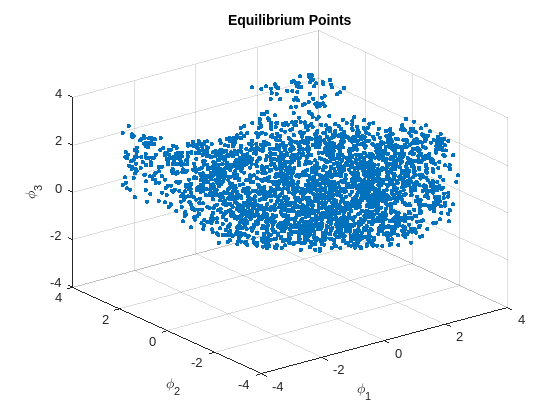

figure;
A = roots;
scatter3(A(:,1),A(:,2),A(:,3),'.');
xlabel('\phi_1');
ylabel('\phi_2');
zlabel('\phi_3');
title('Equilibrium Points');

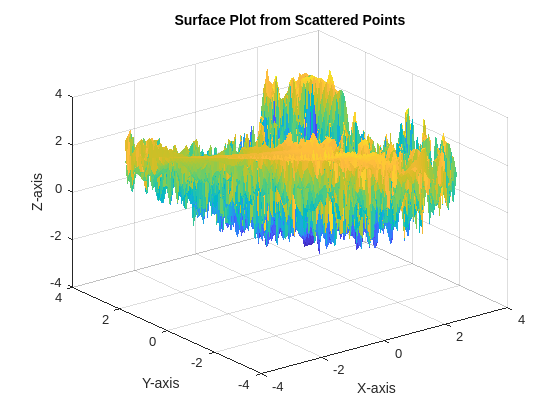



[xq, yq] = meshgrid(linspace(min(roots(:,1)), max(roots(:,1)), 100), linspace(min(roots(:,2)), max(roots(:,2)), 100));
zq = griddata(roots(:,1), roots(:,2), roots(:,3), xq, yq, 'cubic'); % You can use 'linear', 'cubic', or other methods

% Create surface plot
figure;
surf(xq, yq, zq, 'EdgeColor', 'none');
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('Surface Plot from Scattered Points');

f1 = matlabFunction((subs(delta_1, [R,l,alpha], [2.1,1,pi/6])))

f1 = function_handle with value:
    @(phi_1,phi_2,phi_3)pi./6.0-atan2(sin(phi_1+phi_2+phi_3)+sin(phi_1+phi_2)+sin(phi_1),cos(phi_1+phi_2+phi_3)+cos(phi_1+phi_2)+cos(phi_1))


f2 = matlabFunction((subs(delta_2, [R,l,alpha], [2.1,1,pi/6])))

f2 = function_handle with value:
    @(phi_1,phi_2,phi_3)-atan2(sin(phi_1+phi_2+phi_3)+sin(phi_1+phi_2),cos(phi_1+phi_2+phi_3)+cos(phi_1+phi_2))+atan2(-sin(phi_1)+2.1e+1./2.0e+1,-cos(phi_1)+sqrt(3.0).*(2.1e+1./2.0e+1))


f3 = matlabFunction((subs(delta_3, [R,l,alpha], [2.1,1,pi/6])))

f3 = function_handle with value:
    @(phi_1,phi_2,phi_3)-phi_1-phi_2-phi_3+atan2(sin(phi_1+phi_2./2.0).*cos(phi_2./2.0).*-2.0+2.1e+1./2.0e+1,sqrt(3.0).*(2.1e+1./2.0e+1)-cos(phi_1+phi_2./2.0).*cos(phi_2./2.0).*2.0)


M = [-1, -(cos(phi_1)+1)/(2*cos(phi_1)+1),-cos(phi_1)/(2*cos(phi_1)+1);
    -(2*cos(phi_1)+1)/2,-1,-1/2;
    -2*cos(phi_1)*cos(phi_1)-cos(phi_1),-1-cos(phi_1),-1]

$$M = \left(\begin{array}{ccc} -1 & -\frac{\cos\left(\varphi_{1}\right)+1}{2\,\cos\left(\varphi_{1}\right)+1} & -\frac{\cos\left(\varphi_{1}\right)}{2\,\cos\left(\varphi_{1}\right)+1}\\ -\cos\left(\varphi_{1}\right)-\frac{1}{2} & -1 & -\frac{1}{2}\\ -2\,{\cos\left(\varphi_{1}\right)}^{2}-\cos\left(\varphi_{1}\right) & -\cos\left(\varphi_{1}\right)-1 & -1 \end{array}\right)$$

evs = eig(M)

$$evs = \left(\begin{array}{c} 0\\ \cos\left(\varphi_{1}\right)-1\\ -\cos\left(\varphi_{1}\right)-2 \end{array}\right)$$

J = linspace(0,2*pi/3,5000);
f_m_1 = matlabFunction(evs(1));
f_m_2 = matlabFunction(evs(2));
f_m_3 = matlabFunction(evs(3));
% array1 = real(f_m_1(J));
array1 = linspace(0,0,5000);
array2 = real(f_m_2(J));
array3 = real(f_m_3(J));

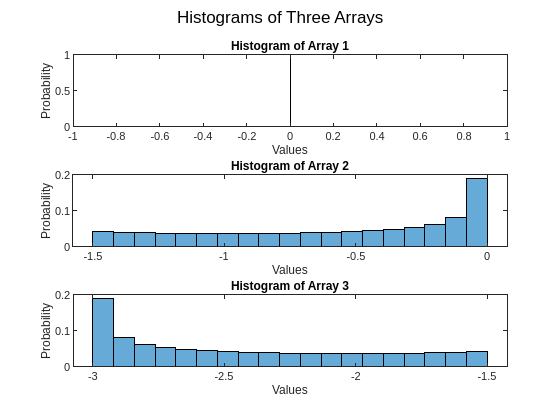

% Plot histograms
figure;

% Histogram for array1
subplot(3, 1, 1);
histogram(array1, 'BinEdges', linspace(min(array1), max(array1), 20), 'Normalization', 'probability');
title('Histogram of Array 1');
xlabel('Values');
ylabel('Probability');

% Histogram for array2
subplot(3, 1, 2);
histogram(array2, 'BinEdges', linspace(min(array2), max(array2), 20), 'Normalization', 'probability');
title('Histogram of Array 2');
xlabel('Values');
ylabel('Probability');

% Histogram for array3
subplot(3, 1, 3);
histogram(array3, 'BinEdges', linspace(min(array3), max(array3), 20), 'Normalization', 'probability');
title('Histogram of Array 3');
xlabel('Values');
ylabel('Probability');

% Adjust layout
sgtitle('Histograms of Three Arrays');

for i = 1:length(array1)
    if array1(i) > 1e-3 && array2(i) > 1e-3
        disp("AAAAAAAAAAAAAAAA")
    elseif array1(i) > 1e-3 && array3(i) > 1e-3
        disp("AAAAAAAAAAAAAAAA")
    elseif array2(i) > 1e-3 && array3(i) > 1e-3
        disp("AAAAAAAAAAAAAAAA")
    end
end